clear

% Define Beam properties
base = sym(0.005);
height = sym(0.005);
I = base*height^3 / 12;
E = sym(1000000);

% Specify load and boundary conditions
syms f(x)
f(x) = 10*height^3;
g = sym(0);
h = sym(0);
m = sym(0);
q = sym(0);

% Compute the Exact Solution
EX = computeExactSolution(E,I,f,g,h,m,q);

% Prepare the FEA solution
nELEM = 2;
eDegree = polynomialDegree(EX.U) - 2;
continuity = eDegree - 1;
contVector = [-1 continuity*ones(1,nELEM-1) -1];

% Compute the FEA solution
FE = main(nELEM, eDegree, contVector, f, g, h, m, q, E*I);

% Get the exact solution at x = 1
EX.U(1)

$$ans = \frac{3}{1000}$$

% Get the FEA solution at x = 1
limit(FE.U,symvar(FE.U),1,'left')

$$ans = \frac{11}{4000}$$

## About the Datastructures

% Exact Solution datastructure
EX

EX = struct with fields:
         f: [1×1 symfun]
       eqn: [1×1 symfun]
      cond: [1×4 sym]
    domain: [0 1]
         U: [1×1 symfun]


EX.f % The forcing function f(x)

$$ans(x) = \frac{1}{800000}$$

EX.eqn % The equation we're solving

$$ans(x) = \frac{\partial^{4}}{\partial x^{4}}u\left(x\right)=\frac{3}{125}$$

EX.cond % The boundary conditions

$$ans = \left(\begin{array}{cccc} u\left(0\right)=0 & \left({\left(\frac{\partial }{\partial x}u\left(x\right)\right)|}_{x=0}\right)=0 & \left({\left(\frac{\partial^{2}}{\partial x^{2}}u\left(x\right)\right)|}_{x=1}\right)=0 & \left({\left(\frac{\partial^{3}}{\partial x^{3}}u\left(x\right)\right)|}_{x=1}\right)=0 \end{array}\right)$$

EX.domain % The domain we're solving over

ans =      0     1


EX.U % The solution u(x)

$$ans(x) = \frac{x^{4}}{1000}-\frac{x^{3}}{250}+\frac{3\,x^{2}}{500}$$


% Finite Element Solution datastructure
FE

FE = struct with fields:
        Elements: [1×2 struct]
          Spline: [1×1 bspline]
               U: [1×1 symfun]
    LinearSystem: [1×1 struct]


FE.Elements % Structure of all the finite elements

ans = 1×2 struct array with fields:
    GDomain
    GNodes
    GDOF
    GbFun
    GBasisFuns
    GInterpFun
    G_EI
    LDomain
    LNodes
    LDOF
    LbFun
    LBasisFuns
    LDerivBasisFuns
    LInterpFun
    GlobalVariate_to_LocalVariate
    LocalVariate_to_GlobalVariate
    Jacobian_Global_to_LocalVariate
    Jacobian_Local_to_GlobalVariate
    Hessian_Global_to_LocalVariate
    Hessian_Local_to_GlobalVariate


FE.Spline % The B-Spline from which we computed things like extraction operators

ans =   bspline with properties:

                 degree: 2
       continuityVector: [-1 1 -1]
               numcells: 2
             knotVector: [0 0 0 0.5000 1 1 1]
      uniqueKnotsVector: [0 0.5000 1]
         referenceNodes: []
                  nodes: [4×1 sym]
    elementConnectivity: [3×2 double]
                  basis: [1×1 struct]
          decomposition: [1×1 struct]


FE.LinearSystem % Structure of the linear system of equations, K d = F

ans = struct with fields:
    K: [2×2 sym]
    F: [2×1 sym]
    d: [4×1 sym]


FE.U % The solution u(x)

$$ans(x) = \left\{ \begin{array}{cl} \frac{11\,{\left(4\,x-2\right)}^{2}}{16000}+\frac{7\,{\left(4\,x-4\right)}^{2}}{32000}-\frac{7\,\left(2\,x-2\right)\,\left(4\,x-2\right)}{4000} & \text{ if }x\in \left[\frac{1}{2},1\right)\\ \frac{11\,{\left(4\,x-2\right)}^{2}}{16000} & \text{ if }x\in \left[\frac{1}{2},1\right)\\ \frac{7\,{\left(4\,x-4\right)}^{2}}{32000}-\frac{7\,\left(2\,x-2\right)\,\left(4\,x-2\right)}{4000} & \text{ if }x\in \left[\frac{1}{2},1\right)\\ 0 & \text{ if }x\in \left[\frac{1}{2},1\right)\\ \frac{7\,x^{2}}{2000} & \text{ if }x\in \left[0,\frac{1}{2}\right)\\ 0 & \text{ if }x\in \left[0,\frac{1}{2}\right) \end{array}\right.$$

## Plots

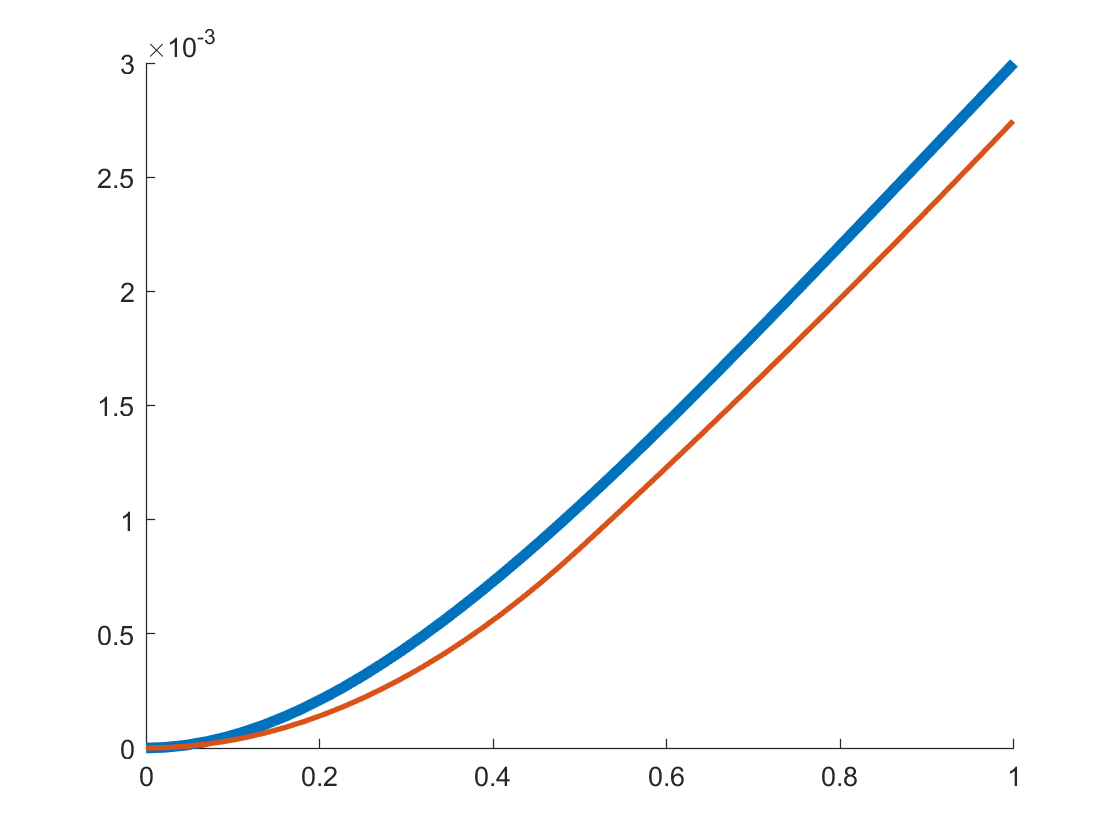

%%% Plot the exact and FEA solutions %%%
figure
hold on
fplot(EX.U,EX.domain,"LineWidth",4)
fplot(FE.U,EX.domain,"LineWidth",2)

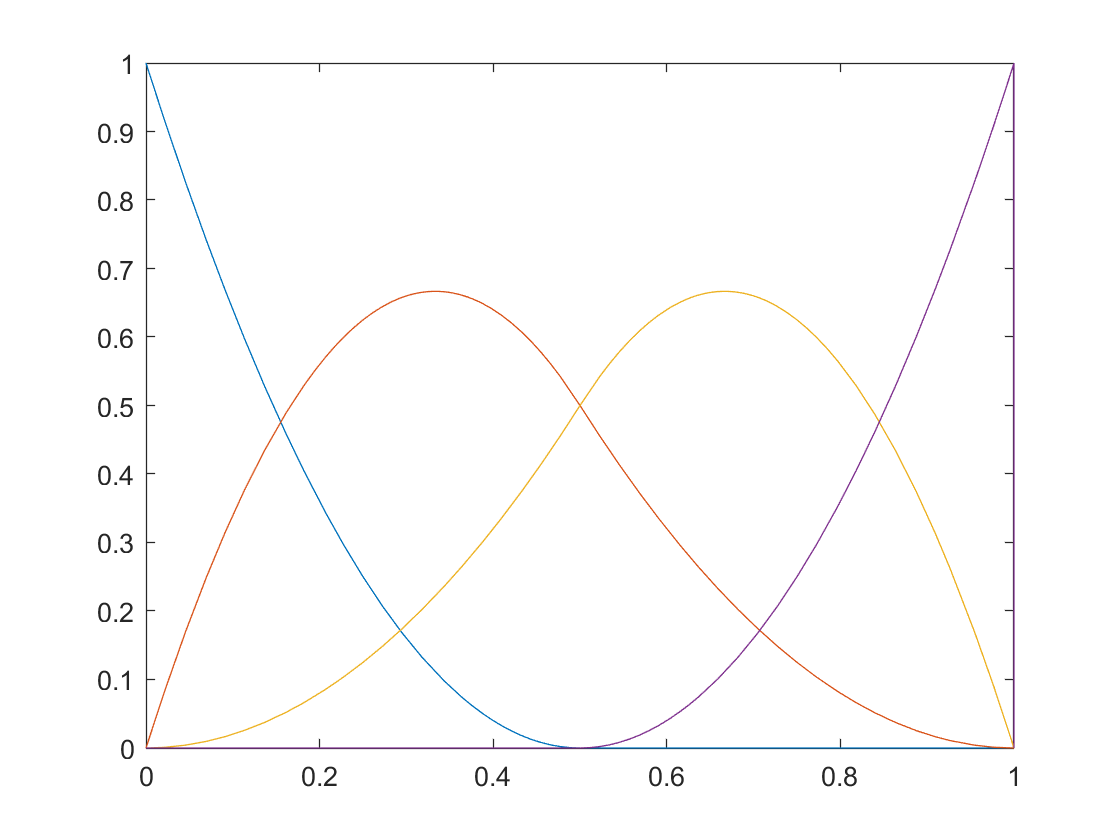


%%% Plot the Spline basis functions %%%
figure
fplot(FE.Spline.basis.functions,EX.domain)

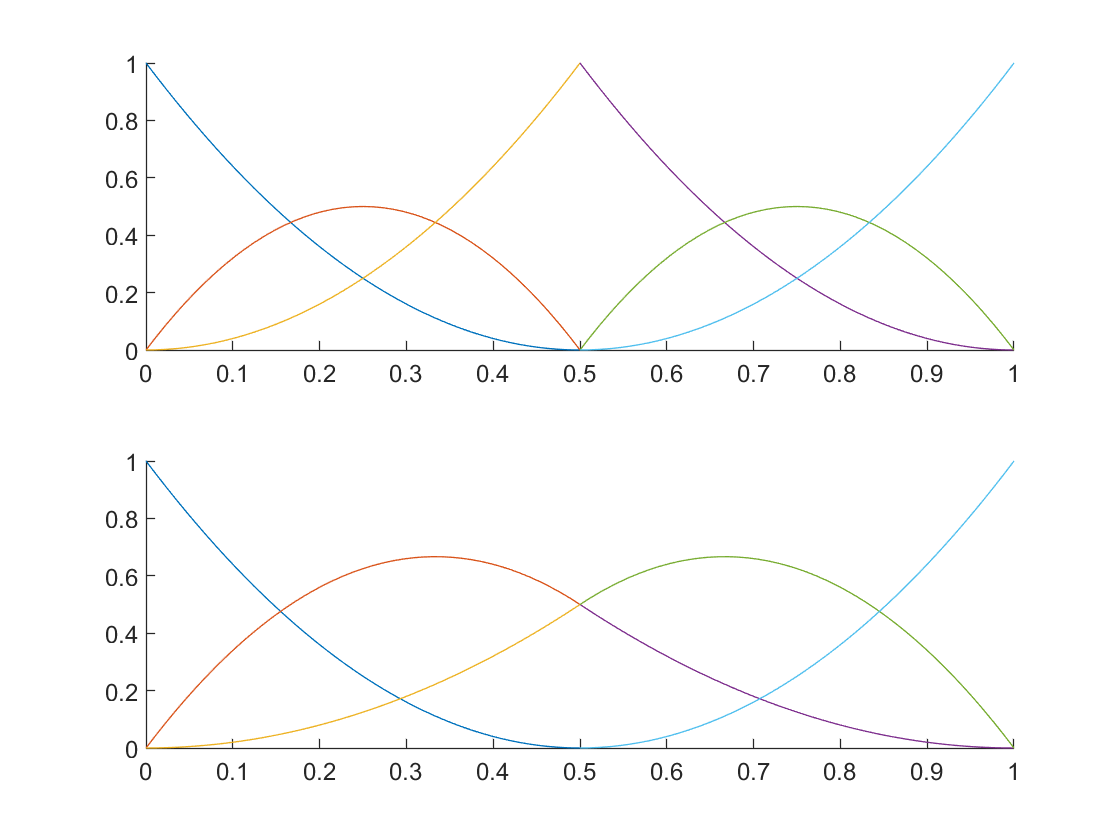


%%% Loop through each element and plot their global basis functions %%%
figure
% First plot the global Bernstein functions
subplot(2,1,1)
hold on
for e = 1:length(FE.Elements)
    fplot(FE.Elements(e).GBasisFuns,FE.Elements(e).GDomain)
end

% Secondly plot the global smooth basis functions
C = FE.Spline.decomposition.localExtractionOperator; % Get element local extraction operators
subplot(2,1,2)
hold on
for e = 1:length(FE.Elements)
    fplot(C{e}*FE.Elements(e).GBasisFuns,FE.Elements(e).GDomain)
end

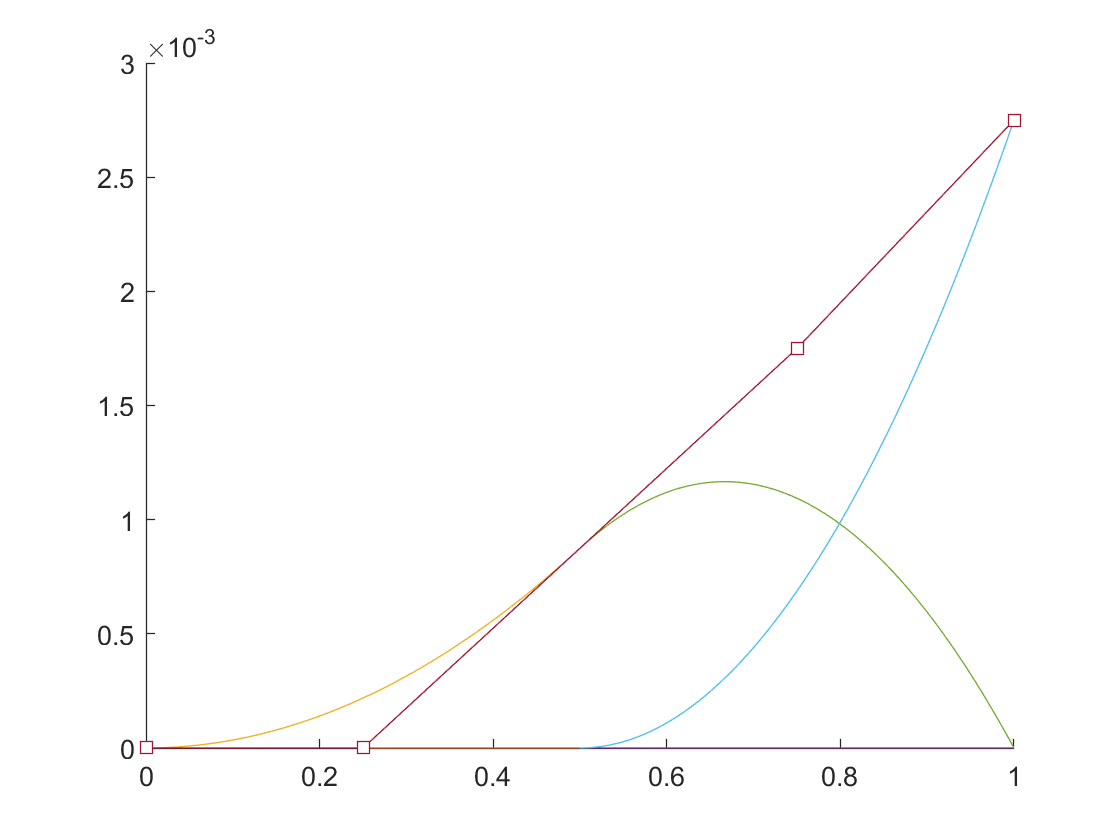


%%% Plot the basis functions scaled by the solution vector %%%
figure
hold on
bFunMap = FE.Spline.decomposition.localExtractionSupportedSplineBases;
for e = 1:length(FE.Elements)
    fplot(C{e}*FE.Elements(e).GBasisFuns .* FE.LinearSystem.d(bFunMap{e}),FE.Elements(e).GDomain)
end
% Add plot of the solution vector
plot(FE.Spline.nodes, FE.LinearSystem.d,'Marker','s','MarkerFaceColor','auto')